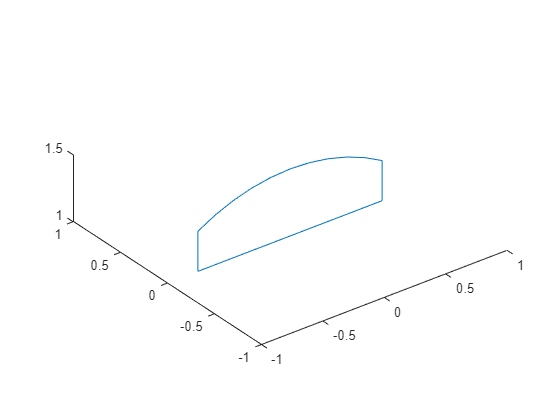

t = linspace(1,2,11)*pi/3; x = 1.5*cos(t); z = 1.5*sin(t);
x = [x,flip(x)]; z = [z, 0*z+1];
x = [x,x(1)]; z = [z,z(1)]; 
y = 0*x;
figure
plot3(x, y, z); daspect([1,1,1])

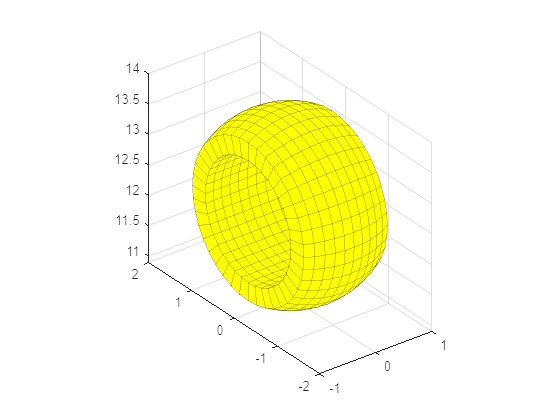

X = x; Y = y; Z = z; xyz = [x; y; z];
M = RotMat([1,0,0],pi/20);
for i = 1:40
    xyz = M*xyz;
    X = [X;xyz(1,:)]; Y = [Y;xyz(2,:)]; Z = [Z;xyz(3,:)];
end
Xs1 = X; Ys1 = Y; Zs1 = Z+6.2;
figure
S1 = surf(Xs1, Ys1, Zs1+6.2, EdgeAlpha=0.2, FaceColor='y'); daspect([1,1,1]);

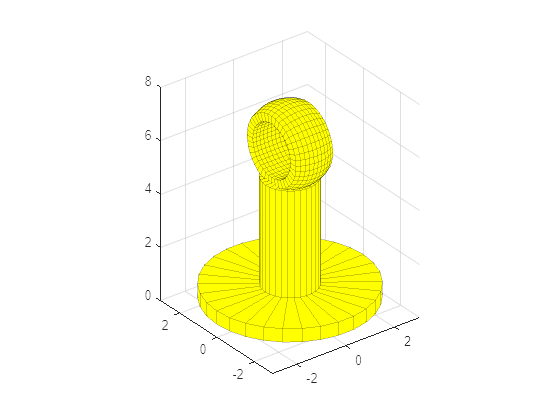

[Xs2, Ys2, Zs2] = cylinder([0,1,1,3,3,0], 30);
Zs2([1,2],:) = 5; Zs2([3,4],:) = 1; Zs2([5,6],:) = 0.5;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); daspect([1,1,1]);

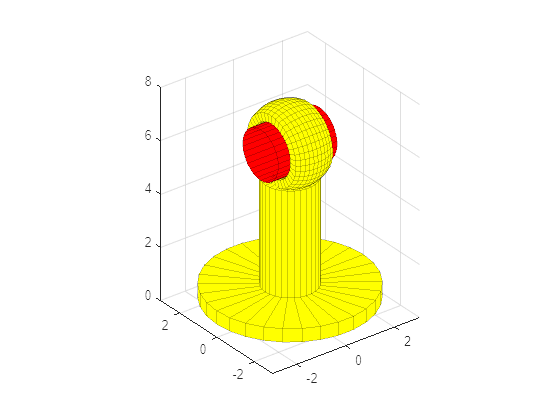

[Z2, Y2, X2] = cylinder(0.95, 30); X2 = X2*2.4-1.2;
Zs3 = Z2 + 6.2; Xs3 = X2; Ys3 = Y2;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r'); daspect([1,1,1]);

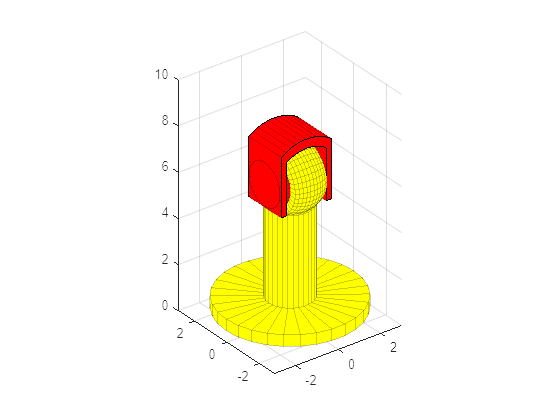

t = linspace(0.9,2.1,11)*pi/3;
x = [1.6*cos(t(1)), 1.6*cos(t), 1.6*cos(t(end)), ....
    2.0*cos(t(end)), 2.0*cos(flip(t)), 2.0*cos(t(1)), 1.6*cos(t(1))];
z = [-1, 1.6*sin(t), -1, -1, 2.0*sin(flip(t)), -1, -1];
y = 0*x;
X3 = [x;x]; Y3 = [y+1; y-1]; Z3 = [z;z];
Xs4 = X3; Ys4 = Y3; Zs4 = Z3 + 6.2;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r');
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r'); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r'); daspect([1,1,1]);

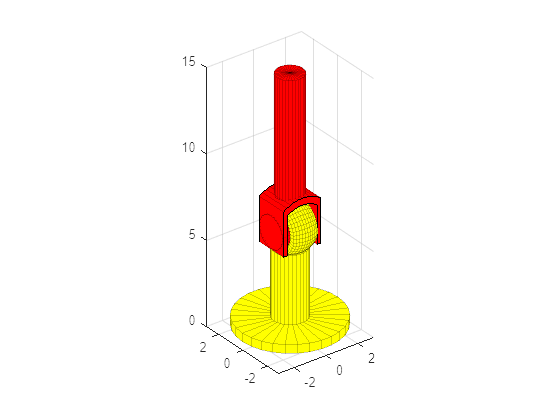

[Xs5, Ys5, Zs5] = cylinder([0,0.8,0.8,0], 30);
Zs5([1,2],:) = 15; Zs5([3,4],:) = 8; 
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r');
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r'); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r');
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); daspect([1,1,1]);

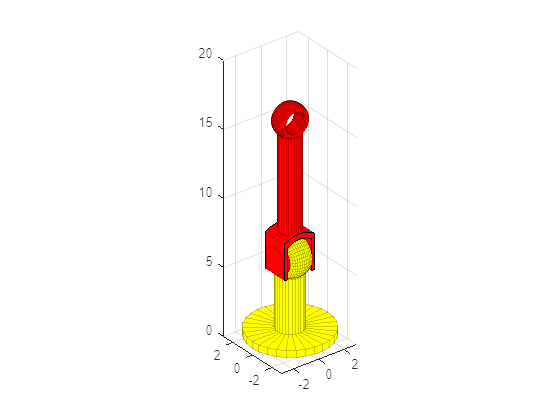

Xs6 = 0.8*Y; Ys6 = 0.8*X; Zs6 = 0.8*Z+16;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r');
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r'); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r');
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); 
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r'); daspect([1,1,1]);

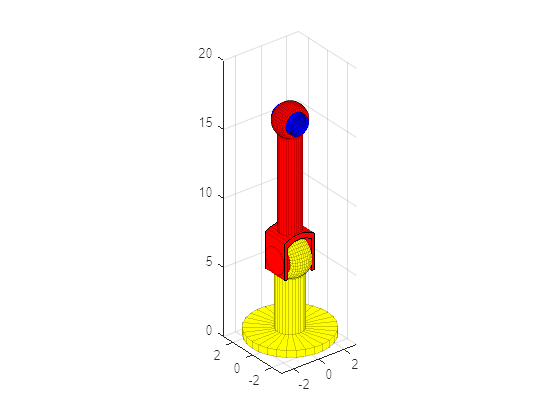

Xs7 = 0.8*Y2; Ys7 = 0.8*X2; Zs7 = 0.8*Z2+16;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r');
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r'); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r');
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); 
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r'); 
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b');daspect([1,1,1]);

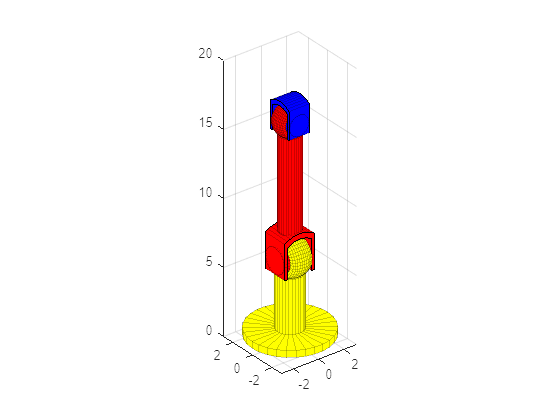

Xs8 = 0.8*Y3; Ys8 = 0.8*X3; Zs8 = 0.8*Z3+16;
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r');
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r'); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r');
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); 
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r'); 
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b');
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); daspect([1,1,1]);

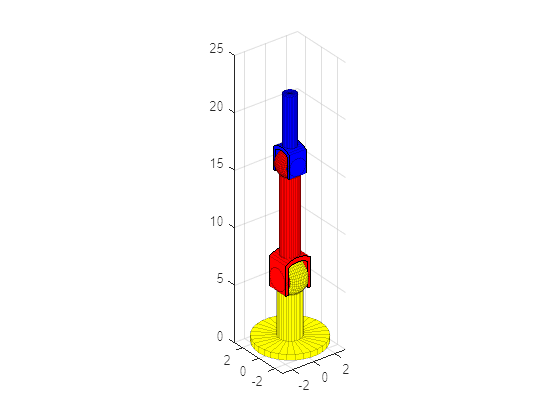

[Xs9, Ys9, Zs9] = cylinder([0,0.6,0.6,0], 30);
Zs9([1,2],:) = 22; Zs9([3,4],:) = 17.5; 
figure
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r');
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r'); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r');
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); 
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r'); 
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b');
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); 
S9 = surf(Xs9, Ys9, Zs9, EdgeAlpha=0.2, FaceColor='b');
daspect([1,1,1]);

t = linspace(0, 2, 201)*pi;
figure
x = 0.5*cos(t); z = 0.5*sin(t); y = 0*x;
plot3(x, y, z); daspect([1,1,1]); hold on;
x = 0.1*cos(t); z = 0.1*sin(t); y = 0*x;
plot3(x, y, z+2); 
v = fsolve(@(v)[v'*v-6.25; (v-[0;-2])'*(v-[0;-2])-4.41], [1;1]); v(2) = -v(2);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


u = fsolve(@(u)[u'*u-12.25; (u-[0;-2])'*(u-[0;-2])-15.21], [1;1]); u(2) = -u(2);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


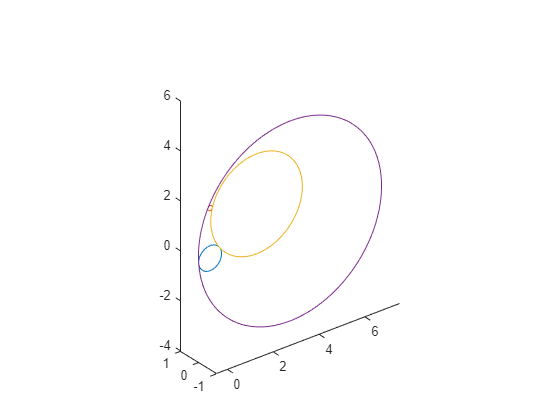

plot3(2*cos(t)+v(1), y, 2*sin(t)+v(2)); 
plot3(4*cos(t)+u(1), y, 4*sin(t)+u(2)); 

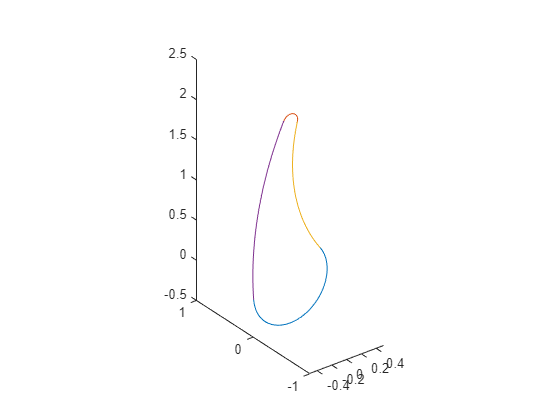

figure
t1a = dir([0;0], v);  t1b = dir([0;0], u);
t1 = linspace(t1b-pi, t1a, 50);
plot3(0.5*cos(t1), 0*t1, 0.5*sin(t1)); hold on; daspect([1,1,1]);

t2a = dir([0;2], v);  t2b = dir([0;2], u);
t2 = linspace(t2b, pi+t2a, 10);
plot3(0.1*cos(t2), 0*t2, 0.1*sin(t2)+2); 

t3a = dir(v,[0;0]);  t3b = dir(v, [0;2]);
t3 = linspace(t3b, 2*pi+t3a, 50);
plot3(2*cos(t3)+v(1), 0*t3, 2*sin(t3)+v(2)); 

t4a = dir(u,[0;0]);  t4b = dir(u, [0;2]);
t4 = linspace(t4b, 2*pi+t4a, 50);
plot3(4*cos(t4)+u(1), 0*t4, 4*sin(t4)+u(2)); 

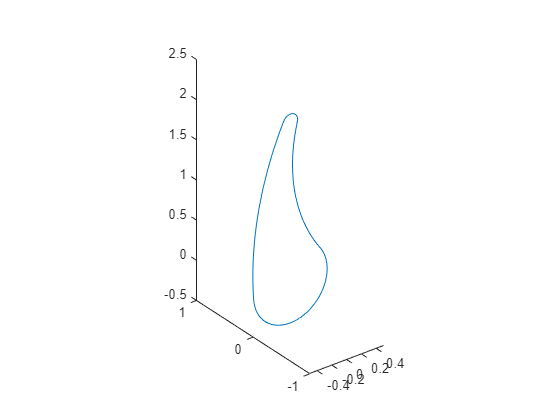

figure
x = [0.5*cos(t1), 2*cos(flip(t3))+v(1), 0.1*cos(t2), 4*cos(t4)+u(1)];
z = [0.5*sin(t1), 2*sin(flip(t3))+v(2), 0.1*sin(t2)+2, 4*sin(t4)+u(2)];
y = 0*x;
plot3(x, y, z);   daspect([1,1,1]);

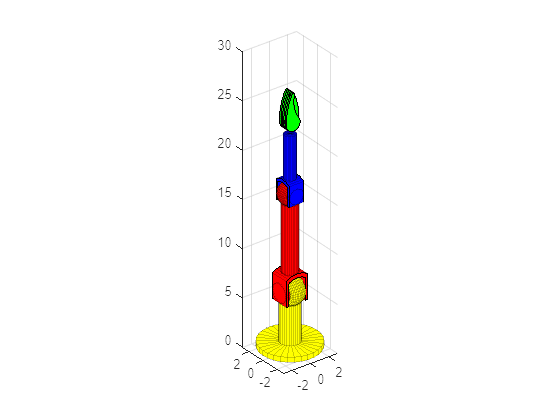

figure
Xs10 = 1.5*[x;x]; Ys10 = [y-0.1;y+0.1]; Zs10 = 1.5*[z;z]+23.2;
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r');
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r'); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r');
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); 
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r'); 
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b');
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); 
S9 = surf(Xs9, Ys9, Zs9, EdgeAlpha=0.2, FaceColor='b');
S10 = surf(Xs10, Ys10, Zs10, EdgeAlpha=0.2, FaceColor='g');
S10a = patch(Xs10(1,:), Ys10(1,:), Zs10(1,:), 'g'); 
S10b = patch(Xs10(2,:), Ys10(2,:), Zs10(2,:), 'g'); 
Xs11 = -Xs10; Ys11 = Ys10-0.2; Zs11 = Zs10;
S11 = surf(Xs11, Ys11, Zs11, EdgeAlpha=0.2, FaceColor='g');
S11a = patch(Xs11(1,:), Ys11(1,:), Zs11(1,:), 'g'); 
S11b = patch(Xs11(2,:), Ys11(2,:), Zs11(2,:), 'g');
Xs12 = -Xs10; Ys12 = Ys10+0.2; Zs12 = Zs10;
S12 = surf(Xs12, Ys12, Zs12, EdgeAlpha=0.2, FaceColor='g');
S12a = patch(Xs12(1,:), Ys12(1,:), Zs12(1,:), 'g'); 
S12b = patch(Xs12(2,:), Ys12(2,:), Zs12(2,:), 'g');
Xs13 = Xs10; Ys13 = Ys10+0.4; Zs13 = Zs10;
S13 = surf(Xs13, Ys13, Zs13, EdgeAlpha=0.2, FaceColor='g');
S13a = patch(Xs13(1,:), Ys13(1,:), Zs13(1,:), 'g'); 
S13b = patch(Xs13(2,:), Ys13(2,:), Zs13(2,:), 'g');
Xs14 = Xs10; Ys14 = Ys10-0.4; Zs14 = Zs10;
S14 = surf(Xs14, Ys14, Zs14, EdgeAlpha=0.2, FaceColor='g');
S14a = patch(Xs14(1,:), Ys14(1,:), Zs14(1,:), 'g'); 
S14b = patch(Xs14(2,:), Ys14(2,:), Zs14(2,:), 'g');
daspect([1,1,1]);

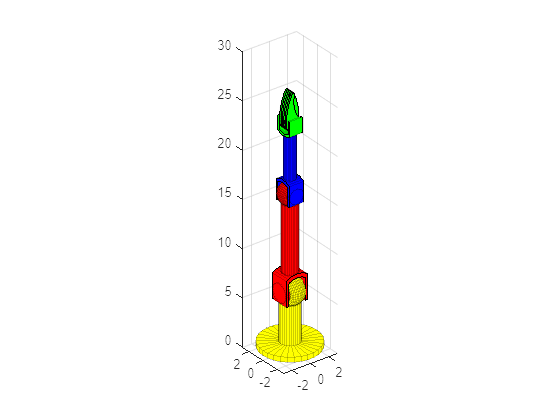

figure
Xs15 = 0.7*Y3; Ys15 = 0.7*X3; Zs15 = -0.6*Z3+23.2;
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r');
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r'); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r');
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); 
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r'); 
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b');
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); 
S9 = surf(Xs9, Ys9, Zs9, EdgeAlpha=0.2, FaceColor='b');
S10 = surf(Xs10, Ys10, Zs10, EdgeAlpha=0.2, FaceColor='g');
S10a = patch(Xs10(1,:), Ys10(1,:), Zs10(1,:), 'g'); 
S10b = patch(Xs10(2,:), Ys10(2,:), Zs10(2,:), 'g'); 
Xs11 = -Xs10; Ys11 = Ys10-0.2; Zs11 = Zs10;
S11 = surf(Xs11, Ys11, Zs11, EdgeAlpha=0.2, FaceColor='g');
S11a = patch(Xs11(1,:), Ys11(1,:), Zs11(1,:), 'g'); 
S11b = patch(Xs11(2,:), Ys11(2,:), Zs11(2,:), 'g');
Xs12 = -Xs10; Ys12 = Ys10+0.2; Zs12 = Zs10;
S12 = surf(Xs12, Ys12, Zs12, EdgeAlpha=0.2, FaceColor='g');
S12a = patch(Xs12(1,:), Ys12(1,:), Zs12(1,:), 'g'); 
S12b = patch(Xs12(2,:), Ys12(2,:), Zs12(2,:), 'g');
Xs13 = Xs10; Ys13 = Ys10+0.4; Zs13 = Zs10;
S13 = surf(Xs13, Ys13, Zs13, EdgeAlpha=0.2, FaceColor='g');
S13a = patch(Xs13(1,:), Ys13(1,:), Zs13(1,:), 'g'); 
S13b = patch(Xs13(2,:), Ys13(2,:), Zs13(2,:), 'g');
Xs14 = Xs10; Ys14 = Ys10-0.4; Zs14 = Zs10;
S14 = surf(Xs14, Ys14, Zs14, EdgeAlpha=0.2, FaceColor='g');
S14a = patch(Xs14(1,:), Ys14(1,:), Zs14(1,:), 'g'); 
S14b = patch(Xs14(2,:), Ys14(2,:), Zs14(2,:), 'g');
S15 = surf(Xs15, Ys15, Zs15, EdgeAlpha=0.2, FaceColor='g');
S15a = patch(Xs15(1,:), Ys15(1,:), Zs15(1,:), 'g'); 
S15b = patch(Xs15(2,:), Ys15(2,:), Zs15(2,:), 'g');
daspect([1,1,1]);

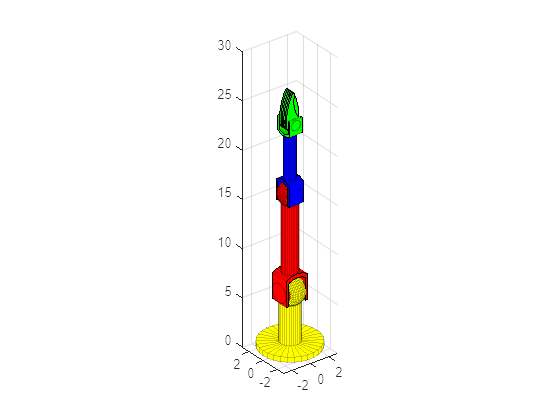

figure
[Z16, X16, Y16] = cylinder(0.5, 30); 
Ys16 = Y16*1.8-0.9; Xs16 = X16; Zs16 = Z16+23.2;
S1 = surf(Xs1, Ys1, Zs1, EdgeAlpha=0.2, FaceColor='y'); hold on;
S2 = surf(Xs2, Ys2, Zs2, EdgeAlpha=0.2, FaceColor='y'); 
S3 = surf(Xs3, Ys3, Zs3, EdgeAlpha=0.2, FaceColor='r');
S4 = surf(Xs4, Ys4, Zs4, EdgeAlpha=0.2, FaceColor='r');
S4a = patch(Xs4(1,:), Ys4(1,:), Zs4(1,:), 'r'); 
S4b = patch(Xs4(2,:), Ys4(2,:), Zs4(2,:), 'r');
S5 = surf(Xs5, Ys5, Zs5, EdgeAlpha=0.2, FaceColor='r'); 
S6 = surf(Xs6, Ys6, Zs6, EdgeAlpha=0.2, FaceColor='r'); 
S7 = surf(Xs7, Ys7, Zs7, EdgeAlpha=0.2, FaceColor='b'); 
S8 = surf(Xs8, Ys8, Zs8, EdgeAlpha=0.2, FaceColor='b');
S8a = patch(Xs8(1,:), Ys8(1,:), Zs8(1,:), 'b'); 
S8b = patch(Xs8(2,:), Ys8(2,:), Zs8(2,:), 'b'); 
S9 = surf(Xs9, Ys9, Zs9, EdgeAlpha=0.2, FaceColor='b');
S10 = surf(Xs10, Ys10, Zs10, EdgeAlpha=0.2, FaceColor='g');
S10a = patch(Xs10(1,:), Ys10(1,:), Zs10(1,:), 'g'); 
S10b = patch(Xs10(2,:), Ys10(2,:), Zs10(2,:), 'g'); 
Xs11 = -Xs10; Ys11 = Ys10-0.2; Zs11 = Zs10;
S11 = surf(Xs11, Ys11, Zs11, EdgeAlpha=0.2, FaceColor='g');
S11a = patch(Xs11(1,:), Ys11(1,:), Zs11(1,:), 'g'); 
S11b = patch(Xs11(2,:), Ys11(2,:), Zs11(2,:), 'g');
Xs12 = -Xs10; Ys12 = Ys10+0.2; Zs12 = Zs10;
S12 = surf(Xs12, Ys12, Zs12, EdgeAlpha=0.2, FaceColor='g');
S12a = patch(Xs12(1,:), Ys12(1,:), Zs12(1,:), 'g'); 
S12b = patch(Xs12(2,:), Ys12(2,:), Zs12(2,:), 'g');
Xs13 = Xs10; Ys13 = Ys10+0.4; Zs13 = Zs10;
S13 = surf(Xs13, Ys13, Zs13, EdgeAlpha=0.2, FaceColor='g');
S13a = patch(Xs13(1,:), Ys13(1,:), Zs13(1,:), 'g'); 
S13b = patch(Xs13(2,:), Ys13(2,:), Zs13(2,:), 'g');
Xs14 = Xs10; Ys14 = Ys10-0.4; Zs14 = Zs10;
S14 = surf(Xs14, Ys14, Zs14, EdgeAlpha=0.2, FaceColor='g');
S14a = patch(Xs14(1,:), Ys14(1,:), Zs14(1,:), 'g'); 
S14b = patch(Xs14(2,:), Ys14(2,:), Zs14(2,:), 'g');
S15 = surf(Xs15, Ys15, Zs15, EdgeAlpha=0.2, FaceColor='g');
S15a = patch(Xs15(1,:), Ys15(1,:), Zs15(1,:), 'g'); 
S15b = patch(Xs15(2,:), Ys15(2,:), Zs15(2,:), 'g');
S16 = surf(Xs16, Ys16, Zs16, EdgeAlpha=0.2, FaceColor='g');
daspect([1,1,1]);

function M = RotMat(U,theta)
c = cos(theta); s = sin(theta); ux = U(1); uy = U(2); uz = U(3);
M = [ux*ux*(1 - c) +    c  uy*ux*(1 - c) - uz*s  uz*ux*(1 - c) + uy*s
     uy*ux*(1 - c) + uz*s  uy*uy*(1 - c) +    c  uz*uy*(1 - c) - ux*s
     uz*ux*(1 - c) - uy*s  uy*uz*(1 - c) + ux*s  uz*uz*(1 - c) +    c]; 
end

function v = dir(pt1, pt2)
    u = pt2-pt1;
    v = atan2(u(2), u(1));
end